# Controller design for a distillation process

#### Definition of the process transfer function

clear 
close all
clc
s=tf('s');

G=[-87.8 1.4;
    -108.2 -1.4]/(75*s+1)

G =
 
  From input 1 to output...
        -87.8
   1:  --------
       75 s + 1
 
        -108.2
   2:  --------
       75 s + 1
 
  From input 2 to output...
         1.4
   1:  --------
       75 s + 1
 
         -1.4
   2:  --------
       75 s + 1
 
Continuous-time transfer function.
Model Properties


#### Definition of the actual process


$$G_p \left(s\right)=\left\lbrack \begin{array}{cc}
k_1 e^{-\theta_1 s}  & 0\\
0 & k_2 e^{-\theta {\;}_2 s} 
\end{array}\right\rbrack G\left(s\right)$$



$$k_i \in \left\lbrack 1\ldotp 2,0\ldotp 8\right\rbrack ,\theta_i \in \left\lbrack 0,60\right\rbrack$$


This give an uncertainty in the DC gain of $\pm 20%$ and a delay of up 1min

In what follows Gp is a realization of the actual process taken as example

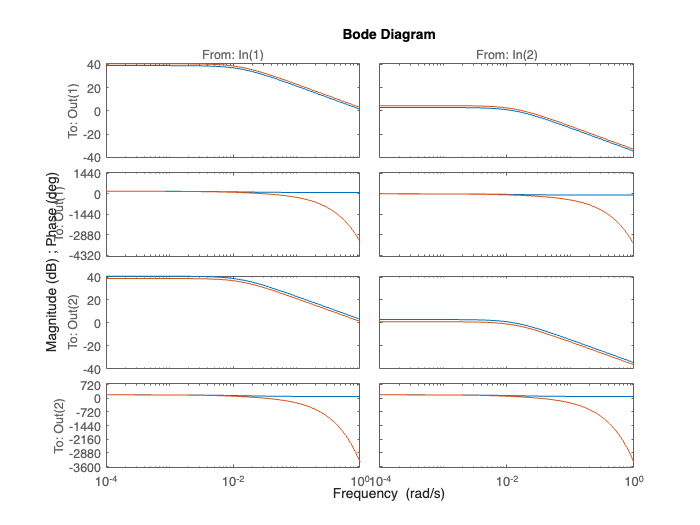

Gt=ss([],[],[],[1.2 0;0 0.8]);
Gt.OutputDelay=[60 60];  
Gp=Gt*G;
bode(G,Gp)

Definition of the multiplicative uncertainty bounds

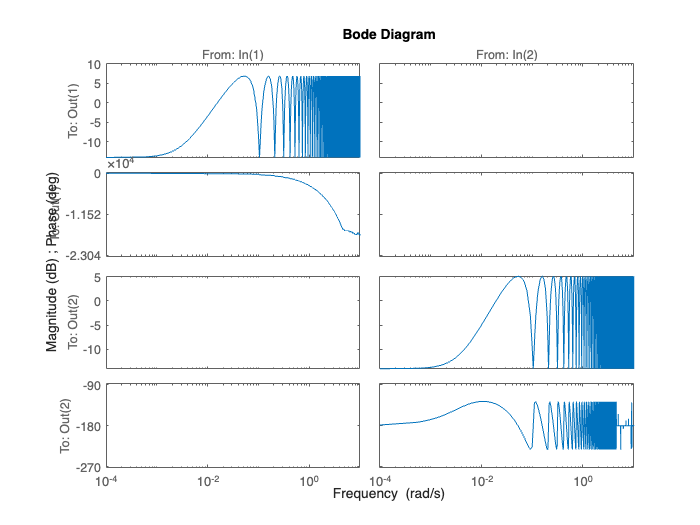

% Gt*G=(I-I+Gt)G=(I+(Gt-I))G=(I+D)G

D=-(eye(2)-Gt);
bode(D)

#### Bounding the uncertainties

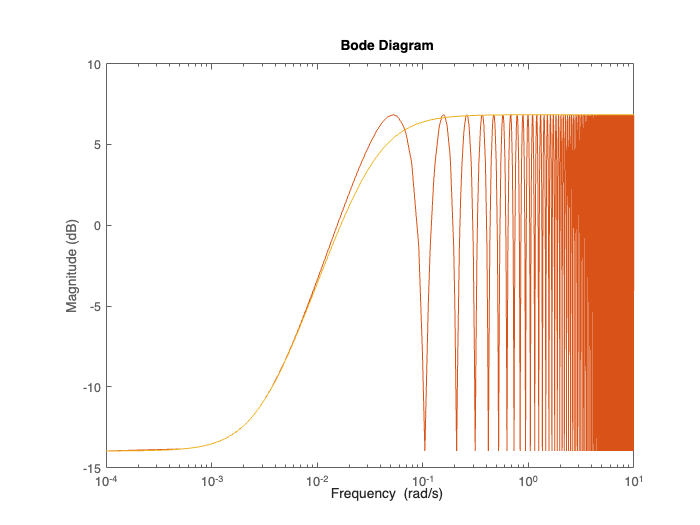

WT=((1.1*s)*60+0.2)/(30*s+1)*eye(2);
bodemag(WT(1,1),D(1,1),pade(D(1,1),1))

#### Controller Design

Specification:

- tracking a step reference with steady-state error less than 1e-3

- Settling-time of about 30min (1800s)

- Sovraelongation less than 20%

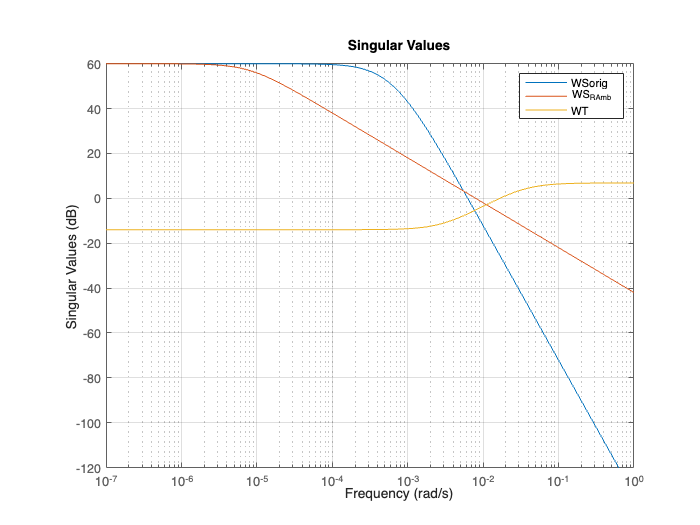

G0=G;

WS_orig=1/((s+1e-3)*(s/5e-4+1)^2)*eye(2);
As=1e-3;
wc=4/500;
M_s=1/(2*0.4);
WS_RAmb = ( s/M_s + wc ) / ( s + wc*As );
%WS_RAmb = ( wc ) / ( s + wc*As );
WS=WS_RAmb;
sigma(WS_orig,WS_RAmb,WT), grid, legend('WSorig','WS_RAmb','WT')

WK = [];   % omit WK*K*S term
[K,CL,GAM] = mixsyn(G0,WS,WK,WT);
GAM

GAM = 0.6334

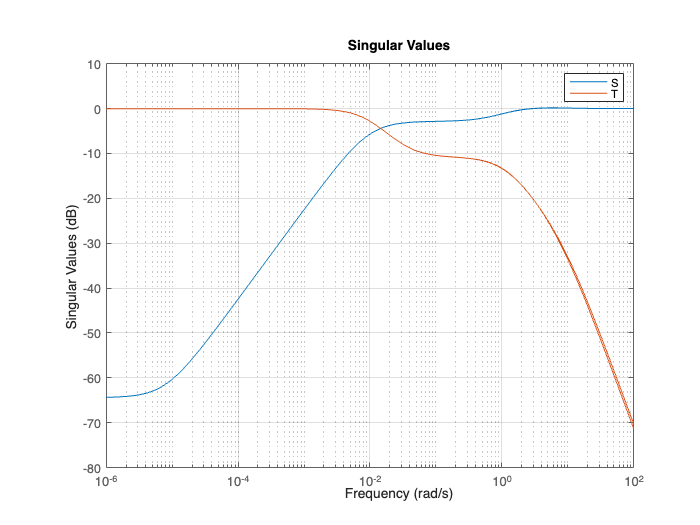

 % Plot design results:
L = G*K;  % loop transfer function
S = feedback(eye(2),L); % sensitivity
T = feedback(L,eye(2));  % complementary sensitivity
sigma(S,T), grid, legend('S','T')

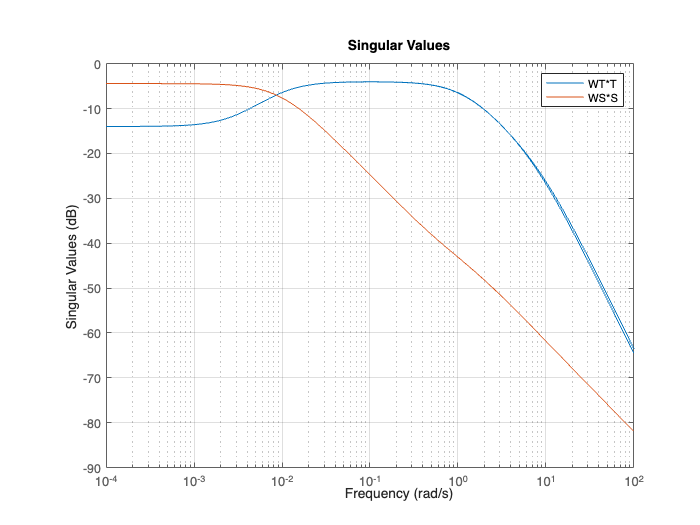

 sigma(WT*T,WS*S), grid, legend('WT*T','WS*S')

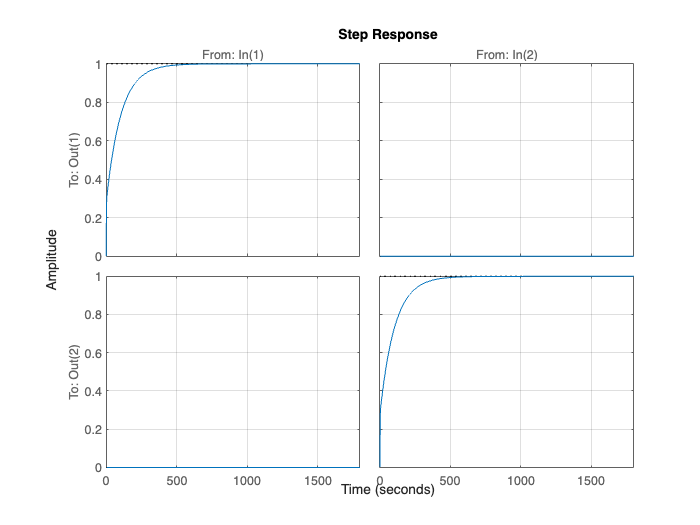

step(T,1800), grid

WK = [1 0;0 1]*1;   
[K2,CL,GAM] = mixsyn(G0,WS,WK,WT);
GAM

GAM = 0.8328

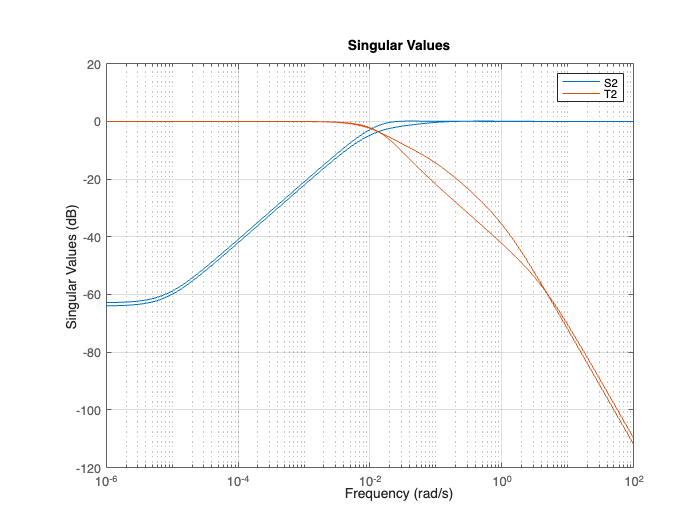

 % Plot design results:
L2 = G*K2;  % loop transfer function
S2 = feedback(eye(2),L2); % sensitivity
T2 = feedback(L2,eye(2));  % complementary sensitivity
sigma(S2,T2), grid, legend('S2','T2')

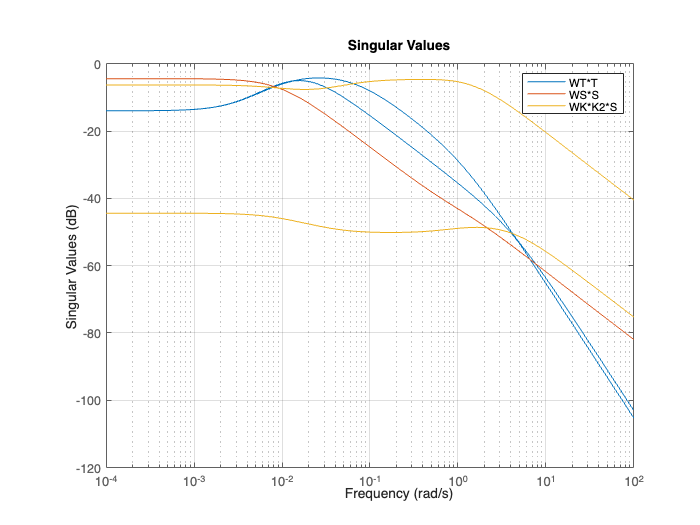

sigma(WT*T2,WS*S,WK*K2*S), grid, legend('WT*T','WS*S','WK*K2*S')

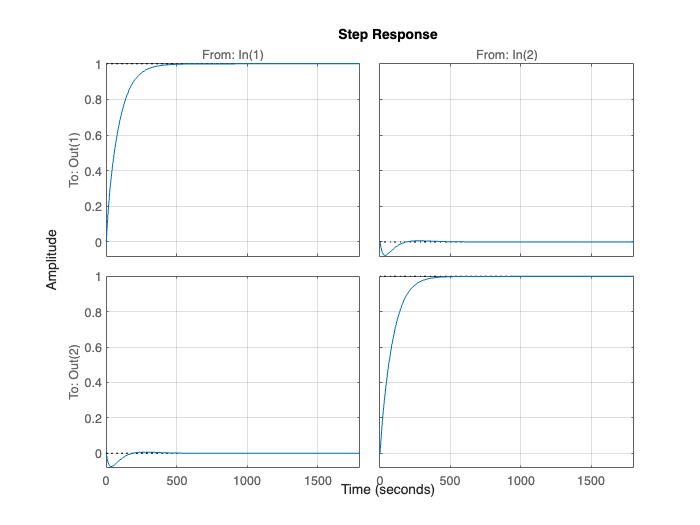

step(T2,1800), grid

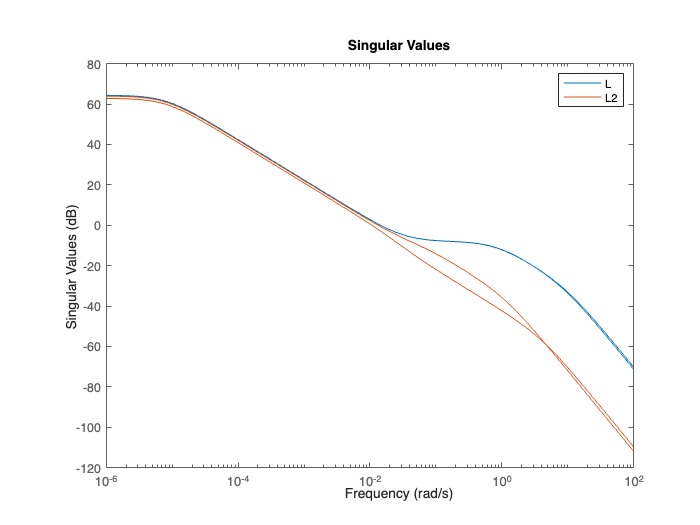

sigma(L,L2), legend('L','L2')